clc;
clear;
close all;

## 添加路径

addpath('plane wave\')

## 参数设置

# MLA

lambda = 647e-6;    % 波长
N = 120;           % 微透镜单元采样点数
rla = -0.94;            % 透镜1的曲率半径
d = 0.3;              % 透镜单元边长
t = 1;            % 透镜厚度
beamStd=1;       %初始高斯光束腰斑直径
material={"F_SILICA"};
MLA1=Lens([rla,inf],t,d,material,lambda);
MLA2=Lens([inf,-rla],t,d,material,lambda);
num=floor(beamStd/d*10);            %数量
if num==0
    num=1;
end
area1 = num*d;           % 光场的面积
area1_2=17;
area2=25;
area3=5;
rate=(d/N);           %采样率（global）
area2=findClosestDivisible(area2,rate);
times=500;
peak=0;
SD=0;

color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)

# Ex-MLA

rla_ex = -2.23;            % 透镜1的曲率半径
d_ex = 0.2;              % 透镜单元边长
t_ex=t;
MLA3=Lens([rla_ex inf],t_ex,d_ex,material,lambda);
distance1 = 1.359;   % 投影距离
distance2 = 120;   % 投影距离
distance3=100;
distance4=4.195;

# Fourier Lens

rfl1 = -128.23;            % 傅里叶透镜的曲率半径（胶合透镜）
rfl2 = -45.71;
rfl3 = 62.75;
dfl = 25.4;              % 傅里叶透镜直径
Dfl = area2;              %采样区域
tfl = [2.5,4];            % 傅里叶透镜厚度

material_fl={'SF5','N-BK7'};

FL=Lens([rfl1,rfl2,rfl3],tfl,dfl,material_fl,lambda);
beam=GaussianBeam(1,beamStd,lambda);
beams=GaussianBeam.defocused(beam,10,N*num,rate);

I=zeros(round(area2/rate));

# Diffuser

diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);

# Objective Lens

n_oil=1;
f_TL=200;
beta=100;
f_OBJ=f_TL/beta;
NA=1.49;
rate2=1/area2*lambda*150;%管镜焦面采样率
area4=(rate2*area2/rate);%管镜焦面计算大小
rate3=1/area4*lambda*f_OBJ/n_oil;%样品面采样率
rP=f_OBJ*NA;
mask=drawCircle(rP/rate2,0,0,round(area3/rate),round(area3/rate));


# Telescope

rt1 = -17.865;            % 透镜1的曲率半径
rt2 = 13.53;           % 透镜2的曲率半径（设为无穷表示平面透镜）
rt3 = 44.17;
dt = 12.7;              % 透镜直径
Dt=5;
tt = [3.5,1.5];            % 透镜厚度
materialt={'N-BK7','SF2'};
distance0 = 45;   % 投影距离
distanceTele=57.6;
teleLens1=Lens([rt1,rt2,rt3],tt,dt,materialt,lambda);
teleLens2=Lens([-rt3,-rt2,-rt1],[1.5,3.5],dt,materialt,lambda);

## 生成透镜相位

%%生成匀光微透镜阵列厚度函数
Lens.lensArrayThickFcn(MLA1,N,num,'square',0,d-0.001);
Lens.lensArrayThickFcn(MLA2,N,num,'square',0,d-0.001);

## 生成傅里叶透镜厚度函数

Lens.lensThickFcn(FL,Dfl,round(area2/rate));

## 生成激发微透镜阵列厚度函数

Lens.lensArrayThickFcn(MLA3,ceil(d_ex/rate),ceil(area2/d_ex),'square',0,d_ex-0.001)

if size(MLA2.thick_edge,1)>size(FL.thick_edge,1)
    siz_FL=size(FL.thick_edge,1);
    siz_MLA2=size(MLA2.thick_edge,1);
    MLA2.thick_edge=MLA2.thick_edge(round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,:);
    MLA2.thick_air=MLA2.thick_air(round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,:);
end
Lens.lensSingle(teleLens1)
Lens.lensSingle(teleLens2)
Lens.lensSingle(MLA1)
Lens.lensSingle(FL);
Lens.lensSingle(MLA2);
Lens.lensSingle(MLA3);
beams=single(beams);
N= single(N);
num= single(num);
Diffuser.diffuserSingle(diffuser)
rate= single(rate);
lambda= single(lambda);
distance1= single(distance1);
distance2= single(distance2);
distance3= single(distance3);
area1= single(area1);
area2= single(area2);
area3= single(area3);
if canUseGPU
    Lens.lensGPUArray(teleLens1)
    Lens.lensGPUArray(teleLens2)
    Lens.lensGPUArray(MLA1)
    Lens.lensGPUArray(FL)
    Lens.lensGPUArray(MLA2);
    Lens.lensGPUArray(MLA3);
    beams=gpuArray(beams);
    N=gpuArray(N);
    num=gpuArray(num);
    Diffuser.diffuserGPUArray(diffuser)
    rate=gpuArray(rate);
    lambda=gpuArray(lambda);
    distance1=gpuArray(distance1);
    distance2=gpuArray(distance2);
    distance3=gpuArray(distance3);
    area1=gpuArray(area1);
    area2=gpuArray(area2);
    area3=gpuArray(area3);
end

## 光场变换

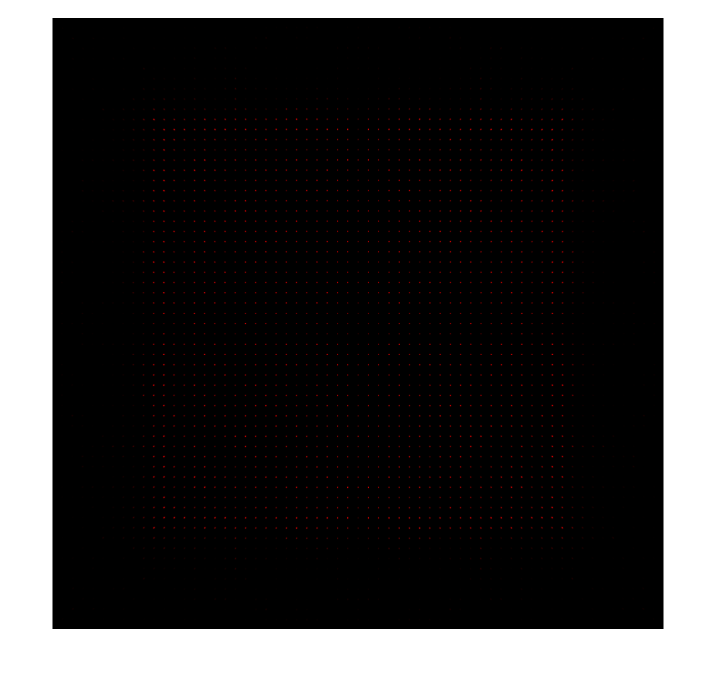

历时 50.612389 秒。


tic
for ii=1:1
    %叠加随机相位
    F = transform(beams, area1, lambda, 1, [rate, rate]);
    %afterLens=ASMinLens(F,teleLens1,lambda,area1);
    %F=  transform(afterLens, area1, lambda, distance0, [rate, rate]);
    %{
    if mod(ii,2)
        [phase1,phase2]=Diffuser.generateDiffuser(diffuser,rate,[N*num,N*num]);
        F=F.*phase1;
    else
        F=F.*phase2;
    end
    %}
    %F=  transform(F, area1, lambda, distanceTele-distance0, [rate, rate]);
    %afterLens=ASMinLens(F,teleLens2,lambda,area1);
    F=transform(F,area1,lambda,10,[rate, rate]);
    afterLens=stepASMinLens(F,MLA1,lambda,area1,200);
    F = transform(afterLens, area1, lambda, distance1, [rate, rate]);
    afterLens = stepASMinLens(F,MLA2,lambda,area1,200);
    %F=FT2Dc(afterLens);
    F = transform(afterLens, area2, lambda, distance2, [rate, rate]);
    afterLens = ASMinLens(F,FL,lambda,area2);
    F = transform(afterLens, 12.8, lambda, distance3, [rate, rate]);

    %afterLens = ASMinLens(F,MLA3,lambda,area2);
    %F = transform(afterLens, area3, lambda, distance4, [rate, rate]);
    
    %F=FT2Dc(F);
    %F=mask.*F;
    %F=FT2Dc(F);
    %F=afterLens;
    I = abs(F).^2;
    %disp(ii)
    %subplot(2,1,1)
    Inorm=(I-min(I,[],'all'))./(max(I,[],'all')-min(I,[],'all'));
    imshow(uint16(Inorm*65536),mymap)
    Inorm=gather(Inorm);
    
    %if mod(ii,20)==0
        
    %meanFWHM=calMeanDia(Inorm,gather(ceil(d_ex/rate)*0.75),0.5)*rate;
    %disp(['平均FWHM=' num2str(meanFWHM*1e3) 'μm'])
    %end
    
    %plot(Inorm(:,3073))
    %hist=imhist(Inorm);
    %[~,peak(end+1)]=max(hist);
    %SD(end+1)=std(Inorm,0,'all');
    %subplot(2,2,3)
    %plot(peak)
    %subplot(2,2,4)
    %plot(SD)
    toc
    drawnow
end

## 显示结果

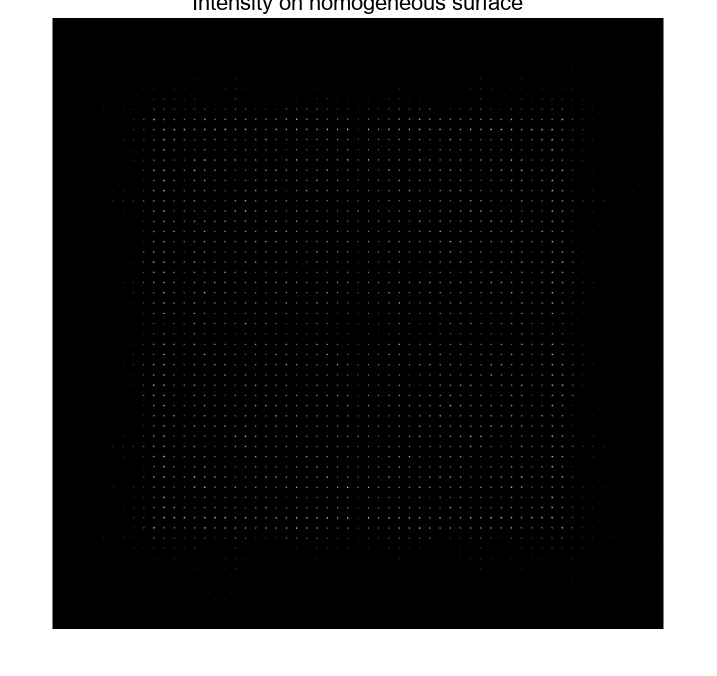

I = gather(I);
imshow(I, [])
title('Intensity on homogeneous surface')